% base code

% q = z/d
z_init = rand(1,1);
d_init = rand(1,1);

loop_cnt = 0;
iter_cnt = 7;
z = zeros(1,iter_cnt);
d = zeros(1,iter_cnt);

abs_z = abs(z_init);
abs_d = abs(d_init);

zero_flag = 0;
infi_flag = 0;
if abs_z <= 0 % less than minimum resolution
    zero_flag = 1;
elseif abs_d <= 0 % less than minimum resolution
    infi_flag = 1;
end

% step 1: normal ensure d less than 2^-1
if (z_init*d_init) > 0
    sign_flag = 1;
else
    sign_flag = -1;
end

if (zero_flag == 0) && (infi_flag == 0)
    loop_abs = abs_d;
    while loop_abs > 2^(-0)
        loop_abs = loop_abs/2;
        loop_cnt = loop_cnt + 1;
    end
    
    while loop_abs < 2^(-1)
        loop_abs = loop_abs*2;
        loop_cnt = loop_cnt - 1;
    end
end

% step 2: init
z(1,1) = abs_z;
d(1,1) = abs_d*2^(-loop_cnt);

% step 3: iter
for idx_i = 2:iter_cnt
    z(1,idx_i) = z(1,idx_i-1)*(2 - d(1,idx_i-1));
    d(1,idx_i) = d(1,idx_i-1)*(2 - d(1,idx_i-1));
end

% step 4: recover
if zero_flag
    q = 0;
elseif infi_flag
    q = inf;
else
    q = z(1,iter_cnt)*2^(-loop_cnt)*sign_flag;
end

div_sys = z_init/d_init;
disp(div_sys);

    0.3063



disp(q);

    0.3063



err = div_sys - q;
disp(err);

     0



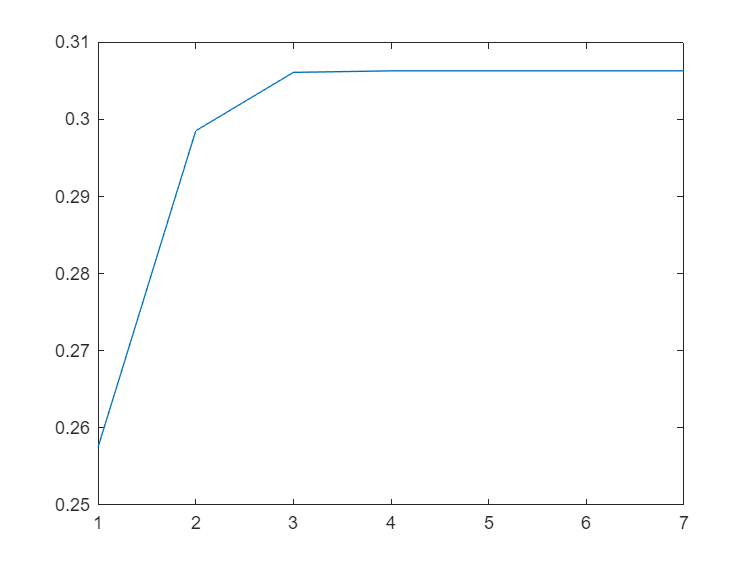


plot(z);